
n=1.14

n = 1.1400

D=0.439

D = 0.4390


R=7.5

R = 7.5000

L=119e-6

L = 1.1900e-04

C=1.25e-6

C = 1.2500e-06


Dp=1-D

Dp = 0.5610


Zn=(-Dp^2*R/(n^2*D^2)) *...
    tf([ ...Numerator
    -D*n^2*L/(Dp^2*R) ...s
    ,1], ...
    [ ...Denumerator
    1])

Zn =
 
  0.0002711 s - 9.424
 
Continuous-time transfer function.




Zd = (Dp^2*R/(n^2*D^2)) * ... Constant
    tf([ ...Numerator
    n^2*L*C/Dp^2, ...s^2
    n^2*L/(Dp^2*R), ...s
    1], ...
    [ ...Denumerator
    R*C, ... s
    1])

Zd =
 
  5.789e-09 s^2 + 0.0006175 s + 9.424
  -----------------------------------
            9.375e-06 s + 1
 
Continuous-time transfer function.



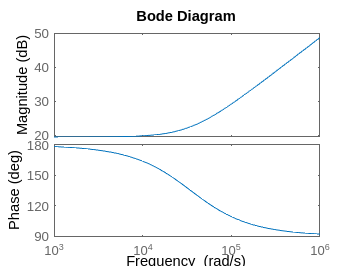





bodeplot(Zn)

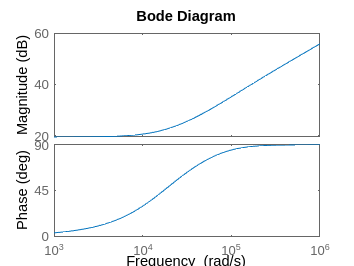

bodeplot(Zd)




zpk(Zn)

ans =
 
  0.00027107 (s-3.477e04)
 
Continuous-time zero/pole/gain model.



zpk(Zd)

ans =
 
  0.00061747 (s+8.821e04) (s+1.846e04)
  ------------------------------------
              (s+1.067e05)
 
Continuous-time zero/pole/gain model.




dcgain(Zd)

ans = 9.4243

dcgain(Zn)

ans = -9.4243


f0=1.846e4

f0 = 18460

f1=1.076e5

f1 = 107600


f0/(2*pi)

ans = 2.9380e+03

f1/(2*pi)

ans = 1.7125e+04


zi=abs(evalfr(Zn,i*f0))

zi = 10.6704

abs(evalfr(Zd,i*f0))

ans = 13.4187


evalfr(Zn,1)

ans = -9.4240


1/(f0*zi)

ans = 5.0768e-06


c=10e-6

c = 1.0000e-05

l=5.8e-6

l = 5.8000e-06

r=0.53

r = 0.5300



p = @(x,y)1/((1/x)+(1/y));



s = tf('s');

Zo=p( ...
    s*l+p( ...
            r, ...
            p( ...
                3*l*s, ...
                1/(s*c) ...
              ) ...
          ) ...
    ,1/(3*c*s))

Zo =
 
           1.009e-15 s^3 + 1.904e-10 s^2 + 2.32e-05 s
  -------------------------------------------------------------
  3.028e-20 s^4 + 5.712e-15 s^3 + 8.7e-10 s^2 + 3.283e-05 s + 1
 
Continuous-time transfer function.





zpk(Zo,'v')

ans =
 
            33333 s (s^2 + 1.887e05s + 2.299e10)
  ---------------------------------------------------------
  (s^2 + 4.023e04s + 1.558e09) (s^2 + 1.484e05s + 2.121e10)
 
Continuous-time zero/pole/gain model.



[z, p, k]=zpkdata(Zo)

z = 1×1 cell array
    {3×1 double}


p = 1×1 cell array
    {4×1 double}


k = 3.3333e+04


z{1}

ans = 	1.0e+05 *

   0.0000 + 0.0000i
  -0.9434 + 1.1870i
  -0.9434 - 1.1870i


p{1}

ans = 	1.0e+05 *

  -0.7422 + 1.2529i
  -0.7422 - 1.2529i
  -0.2012 + 0.3395i
  -0.2012 - 0.3395i


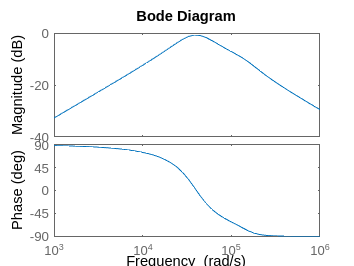





bodeplot(Zo)

%Second iteration
c=10e-6

c = 1.0000e-05

l=110e-6

l = 1.1000e-04

r=0.53

r = 0.5300



p = @(x,y)1/((1/x)+(1/y));



s = tf('s');

Zo=p( ...
    s*l+p( ...
            r, ...
            p( ...
                3*l*s, ...
                1/(s*c) ...
              ) ...
          ) ...
    ,1/(3*c*s))

Zo =
 
             3.63e-13 s^3 + 6.849e-08 s^2 + 0.00044 s
  --------------------------------------------------------------
  1.089e-17 s^4 + 2.055e-12 s^3 + 1.65e-08 s^2 + 0.0006226 s + 1
 
Continuous-time transfer function.





zpk(Zo,'v')

ans =
 
          33333 s (s+1.82e05) (s+6659)
  ---------------------------------------------
  (s+1.821e05) (s+1664) (s^2 + 4948s + 3.03e08)
 
Continuous-time zero/pole/gain model.



[z, p, k]=zpkdata(Zo)

z = 1×1 cell array
    {3×1 double}


p = 1×1 cell array
    {4×1 double}


k = 3.3333e+04


z{1}

ans = 	1.0e+05 *

         0
   -1.8202
   -0.0666


p{1}

ans = 	1.0e+05 *

  -1.8207 + 0.0000i
  -0.0247 + 0.1723i
  -0.0247 - 0.1723i
  -0.0166 + 0.0000i


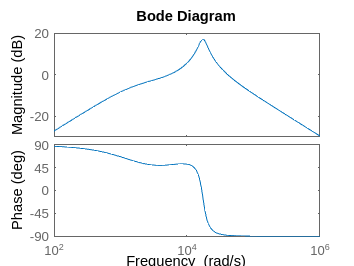





bodeplot(Zo)